# Longitudinal Vehicle

This block is part of Simscape Driveline.

## Resisting Force and Power

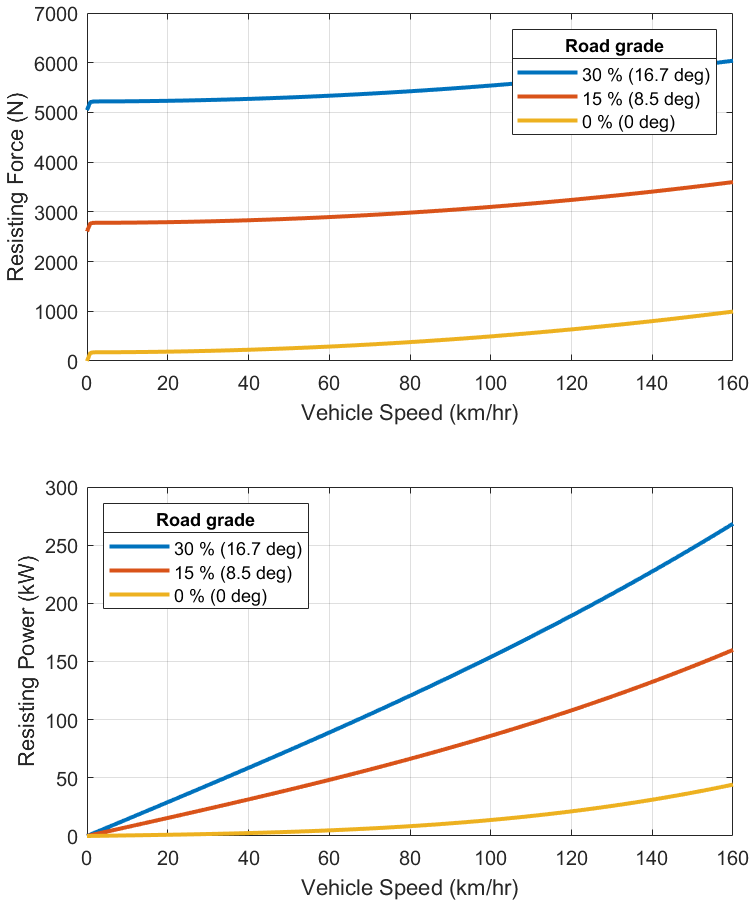

name = "Vehicle1DDriveline";

mdl = name + "_refsub";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load parameters
Vehicle1D_harness_setup

% Select subsystem
set_param(0, "CurrentSystem", mdl)

% Select block and collect block parameters
set_param(gcs, "CurrentBlock", "Longitudinal Vehicle")

block_info = Vehicle1DUtility.getVehicle1DDrivelineBlockInfo(gcbh);

fig = Vehicle1DUtility.plotRoadLoad( ...
  "VehicleMass_kg", block_info.M_e_kg, ...
  "RoadLoadA_N", block_info.A_rl_N, ...
  "RoadLoadB_N_per_kph", block_info.B_rl_N_per_kph, ...
  "RoadLoadC_N_per_kph2", block_info.C_rl_N_per_kph2, ...
  "GravitationalAcceleration_m_per_s2", block_info.grav_m_per_s2, ...
  "VehicleSpeedVector_kph", linspace(0, 160, 200), ...
  "RoadGradeVector_pct", [30, 15, 0] );

fig.Position(3:4) = [500 600];  % width height

imgPath = fullfile( currentProject().RootFolder, "Components", ...
  "Vehicle1D", "images", "image_"+name+"_ResistingForcePower.png");

exportgraphics(fig, imgPath)

*Copyright 2022 The Mathworks, Inc.*